# PHYS 4030 Homework 4

**Name:** Johannes Irnawan

# Part 1: Reproducing Newman (2012) Figure 9.7

### Idea

In this exercise, we want to reproduce Newman (2012) Figure 9.7. We start with the general 1D wave equation:


$$\frac{\partial^2 \;u}{\partial t^2 }=c^2 \frac{\partial^2 \;u}{\partial x^2 }$$


where $c=\textrm{speed}\;\textrm{of}\;\textrm{propagation}$ and $u=u\left(x,t\right)=\textrm{displacement}\;\textrm{function}$. This wave equation is bounded by $x\in \left\lbrack 0,L\right\rbrack$ and $t\in \left\lbrack 0,\infty \right)$, however, we want $t$ to end at a certain $t_{\textrm{end}}$ so that our calculation does not continue forever.

To solve the wave equation, we need initial conditions at $t=0$ for $0\le x\le L$:

- 
$$u\left(x,0\right)=f\left(x\right)$$


- 
$$\frac{\partial u}{\partial t}=\dot{u} \left(x,0\right)=g\left(x\right)$$


and boundary conditions:

- 
$$u\left(0,t\right)=\phi \left(t\right)$$


- 
$$u\left(L,t\right)=\psi \left(t\right)$$


### Setting Up

We can consider the wave that we want to produce to be a wave at rest where $u\left(x,0\right)=0$ and is bounded at $u\left(0,t\right)=u\left(L,t\right)=0$. At $t=0$, there is a force at $x=d$ that struck our wave, giving us a velocity $\dot{u} \left(x,0\right)=\dot{u_0 }$. 

For our wave, we want the wave equation bounded within $x\in \left\lbrack 0,L=1\right\rbrack$ and $t\in \left\lbrack 0,t_{\textrm{end}} =1s\right\rbrack$. Our initial and boundary conditions are:

- 
$$u\left(0,t\right)=u\left(1,t\right)=0$$


- 
$$u\left(x,0\right)=0$$


- 
$$\frac{\partial u}{\partial t}{\left|\right.}_{t=0} =\dot{u} \left(x,0\right)=\dot{u_0 } =Cx\left(1-x\right)\exp \left\lbrack -\frac{{\left(x-d\right)}^2 }{2\sigma^2 }\right\rbrack$$


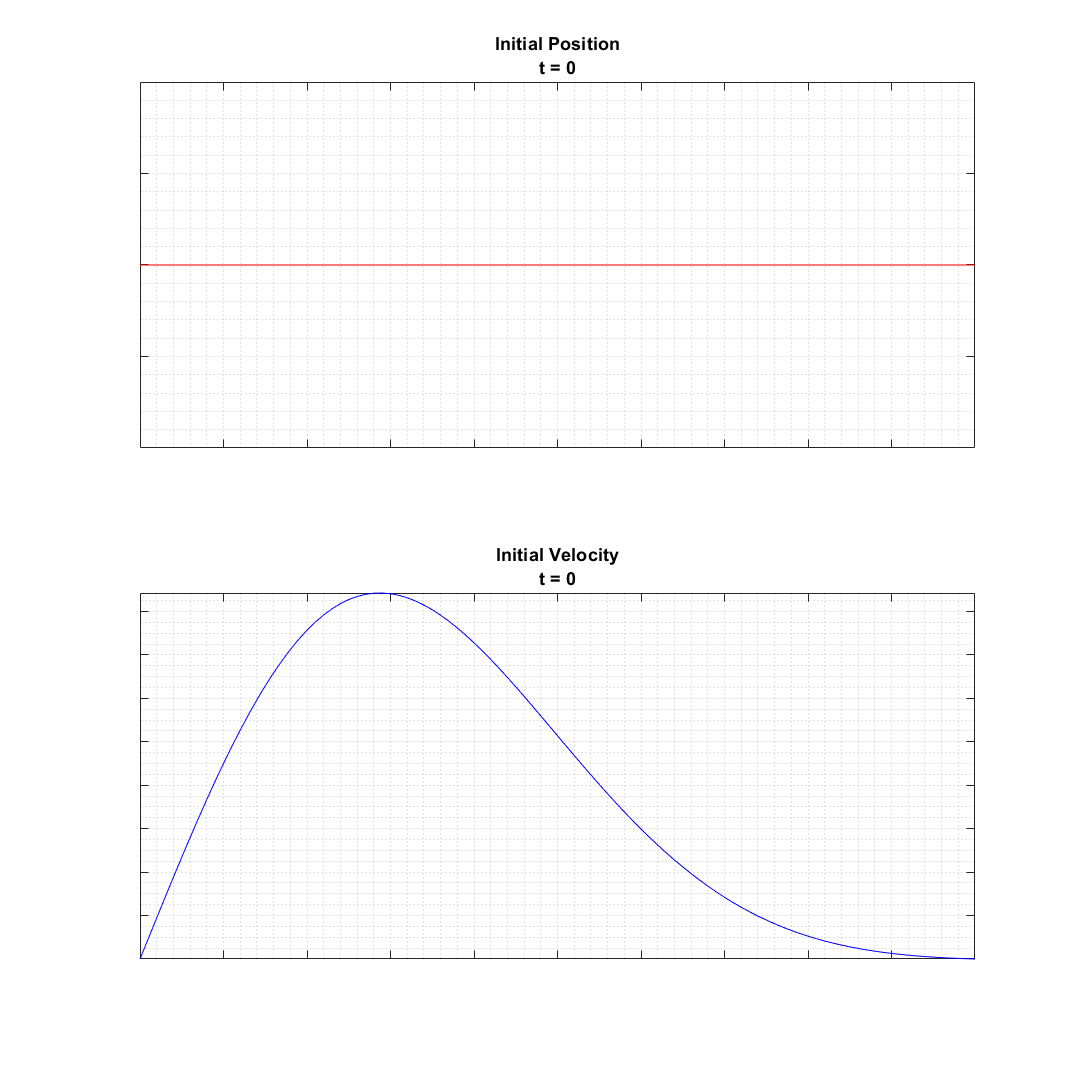

% Cleaning up the memory
clear; clc; clf;

% Parameters:
L = 1;              % Boundary L at 1m from x=0
d = 0.1;            % Force applied at d
C = 1/1E-3;         % Amplitude coefficient for given speed
c = 100;            % Speed of propagation
sigm = 0.3;         % Force is distributed with a description
x_total = 100;      % Total step in x
h_step = L/x_total; % Step size in x
k_step = 1E-6;      % Step size in t
t_end = 0.1;

% Initial & Boundary Conditions
initial.x = linspace(0,L,x_total+1);
domain.x = initial.x;
initial.t = 0;
domain.t = initial.t:k_step:t_end;
initial.u = zeros(1,length(initial.x));
initial.v = C*(initial.x).*(L-(initial.x))/L^2.*exp(-((initial.x)-d).^2./(2*sigm^2));

% Plotting initial positions and velocities
clf; figure();
figure_1 = figure('Position', [100, 100, 1600, 1600]);
subplot(2,1,1)
plot(initial.x,initial.u,'r');
grid minor, axis([0 1 -1 1])
title({'Initial Position','t = 0'})
set(gca,'xticklabel',[],'yticklabel',[])
subplot(2,1,2)
plot(initial.x,initial.v,'b')
grid minor, axis([0 1 min(initial.v) max(initial.v)])
title({'Initial Velocity','t = 0'})
set(gca,'xticklabel',[],'yticklabel',[])

### Reproducing the Graph

To reproduce the figure given by Newman (2012), the wave equation will be numerically solved using the FTCS scheme (Newman, 2012). The FTCS scheme is given by:


$$u_x^{t+k} =u_x^t +k{\dot{u} }_x^t$$



$${\dot{u} }_x^{t+k} ={\dot{u} }_x^t +\frac{\lambda^2 }{k}\left(u_{x+h}^t +u_{x-h}^t -2u_x^t \right)$$


where $k=\textrm{time}\;\textrm{spacing}$, $h=\textrm{discreet}\;x\;\textrm{points}\;\textrm{spacing}$, $\lambda =ck/h$, and $c=\textrm{speed}\;\textrm{of}\;\textrm{propagation}$.

% Setting up the PDE
lambda = k_step*c/h_step;
u = zeros(length(domain.t),length(domain.x));
u(1,:) = initial.u;
v = zeros(length(domain.t),length(domain.x));
v(1,:) = initial.v;
% Note: The index (k,h) represents (time index, position index)

% Numerical solution:
for n=2:length(domain.t)
    u(n,2:x_total)= u(n-1,2:x_total)+ k_step*v(n-1,2:x_total);
    v(n,2:x_total)= v(n-1,2:x_total) + ...
        lambda^2/k_step*(u(n-1,3:x_total+1)+...
        u(n-1,1:x_total-1)-2*u(n-1,2:x_total));
end

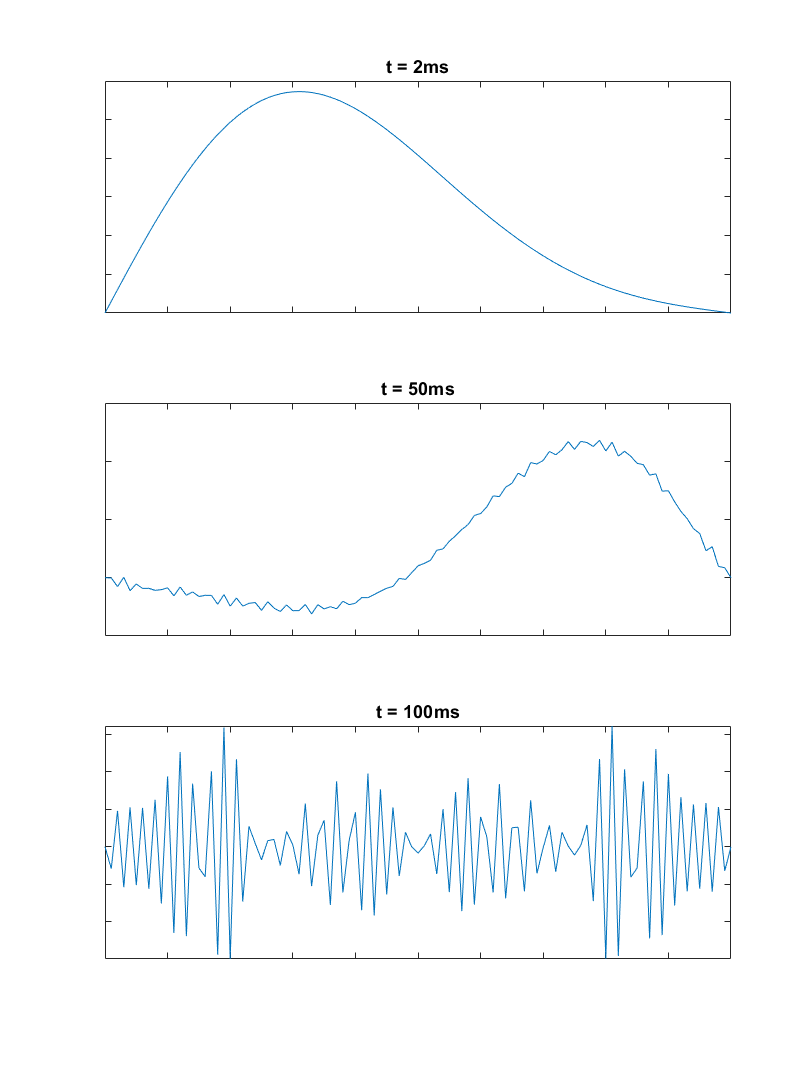

% Plotting for t = 2ms, 50ms, 100ms
clf; figure();
figure_1 = figure('Position', [100, 100, 1200, 1600]);
time = [0.002 0.05 0.1];        % T in seconds to graph
index = time/k_step;
for k = 1:3
    subplot(3,1,k)
    plot(domain.x,u(round(index(k)),:))
    grid off, title(['t = ',num2str(index(k)/1000),'ms'])
    set(gca,'xticklabel',[],'yticklabel',[])
end

# Part 2: 2-D Poisson Equation

### Idea

In this exercise, we want to evaluate Poisson equation:


$$\nabla^2 \phi =-\frac{\rho }{\epsilon_0 }$$


where $\phi =\textrm{electric}\;\textrm{potential}$, $\rho =\textrm{charge}\;\textrm{density}$, and $\epsilon_0 =\textrm{permittivity}\;\textrm{of}\;\textrm{free}\;\textrm{space}$. The Poisson equation we want to evaluate in this part is the 2-D Poisson equation:


$$\frac{\partial^2 \;}{\partial x^2 }\phi \left(x,y\right)+\frac{\partial^2 }{\partial y^2 }\phi \left(x,y\right)=-\frac{\rho \left(x,y\right)}{\epsilon_0 }$$


To solve the 2D Poisson equation, we need initial and boundary conditions:

- The space is bounded in $x\in \left\lbrack 0,L\right\rbrack$ and $y\in \left\lbrack 0,L\right\rbrack$.

- The voltage is zero at the walls: $\phi \left(0,y\right)=\phi \left(x,0\right)=\phi \left(L,y\right)=\phi \left(x,L\right)=0$

### Setting Up

We consider a 2D box with some square charges of $20\textrm{cm}$ by $20\textrm{cm}$ with charge density of $\pm 1{\textrm{cm}}^{-2}$. We also consider evaluating the equation using $\epsilon_0 =1$. Hence, our conditions are:

- 
$$\epsilon_0 =1$$


- The space is bounded in $x\in \left\lbrack 0,L\right\rbrack$ and $y\in \left\lbrack 0,L\right\rbrack$ where $L=100\;\textrm{cm}$.

- The voltage is zero at the walls: $\phi \left(0,y\right)=\phi \left(x,0\right)=\phi \left(L,y\right)=\phi \left(x,L\right)=0$

- Charge density 1: $\rho_1 =-1\;{\textrm{cm}}^{-2}$ at $x_1 \in \left\lbrack 20\;\textrm{cm},40\;\textrm{cm}\right\rbrack$ and $y_1 \in \left\lbrack 20\;\textrm{cm},40\;\textrm{cm}\right\rbrack$

- Charge density 2: $\rho_2 =1\;{\textrm{cm}}^{-2}$ at $x_2 \in \left\lbrack 25\;\textrm{cm},45\;\textrm{cm}\right\rbrack$ and $y_2 \in \left\lbrack 45\;\textrm{cm},65\;\textrm{cm}\right\rbrack$

- Charge density 3: $\rho_3 =-1\;{\textrm{cm}}^{-2}$ at $x_3 \in \left\lbrack 55\;\textrm{cm},75\;\textrm{cm}\right\rbrack$ and $y_3 \in \left\lbrack 35\;\textrm{cm},55\;\textrm{cm}\right\rbrack$

- Charge density 4: $\rho_4 =1\;{\textrm{cm}}^{-2}$ at $x_4 \in \left\lbrack 60\;\textrm{cm},80\;\textrm{cm}\right\rbrack$ and $y_4 \in \left\lbrack 60\;\textrm{cm},80\;\textrm{cm}\right\rbrack$

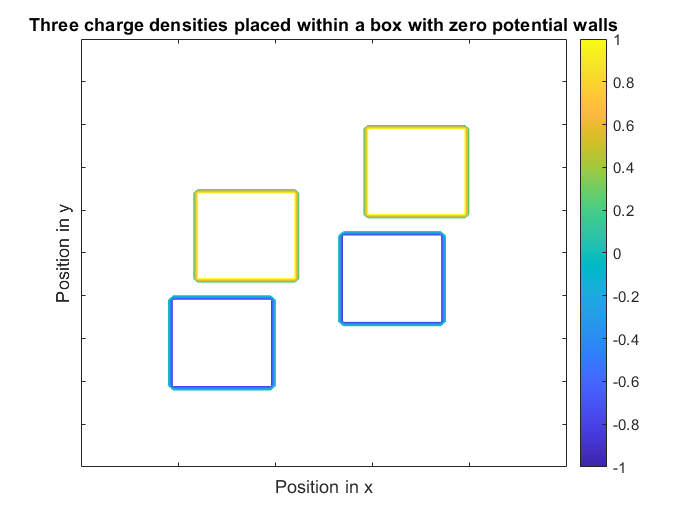

% Cleaning up the memory
clear; clc; clf;

% Parameters
L = 100;                % Boundary L = 100 cm
h_step = 1;             % Grid spacing h = 1 cm
acc_target = 1E-6;      % Target Accuracy
x = 0:h_step:L;         % x points
y = 0:h_step:L;         % y points
[X,Y] = meshgrid(x,y);  % x and y as meshgrid

% Charge Densities
rho = zeros(L+1,L+1);
position.rho_1 = [20 40;20 40];
density.rho_1 = -1;
for k = position.rho_1(1,1):position.rho_1(1,2)
    for j = position.rho_1(2,1):position.rho_1(2,2)
        rho(j,k) = density.rho_1;
    end
end
position.rho_2 = [25 45;45 65];
density.rho_2 = 1;
for k = position.rho_2(1,1):position.rho_2(1,2)
    for j = position.rho_2(2,1):position.rho_2(2,2)
        rho(j,k) = density.rho_2;
    end
end
position.rho_3 = [55 75;35 55];
density.rho_3 = -1;
for k = position.rho_3(1,1):position.rho_3(1,2)
    for j = position.rho_3(2,1):position.rho_3(2,2)
        rho(j,k) = density.rho_3;
    end
end
position.rho_4 = [60 80;60 80];
density.rho_4 = 1;
for k = position.rho_4(1,1):position.rho_4(1,2)
    for j = position.rho_4(2,1):position.rho_4(2,2)
        rho(j,k) = density.rho_4;
    end
end

%{
Note that the index is from 1 to L+1. This is because we need the first
index to represent (0,0), but MATLAB does not start with index 0.
%}

% Plotting Charge Densities
clf; figure();
contour(X,Y,rho)
xlabel('Position in x'), ylabel('Position in y')
title('Three charge densities placed within a box with zero potential walls')
set(gca,'xticklabel',[],'yticklabel',[])
colorbar

### Numerical Solution to 2D Poisson Equation

The numerical solution to 2D Poisson equation is given by the Gauss-Seidel method:


$$\varphi_{j,k}^{t+1} =\frac{h^2 }{4}\rho_{j,k} +\frac{1}{4}\left(\varphi_{j-1,k}^{t+1} +\varphi_{j+1,k}^t +\varphi_{j,k-1}^{t+1} +\varphi_{j,k+1}^t \right)$$


where $h=\textrm{spatial}\;\textrm{spacing}$, $\rho_{j,k} =\textrm{charge}\;\textrm{density}\;\textrm{at}\;j,k$, $\varphi_{j,k} =\textrm{electric}\;\textrm{potential}$, and $t=\textrm{iteration}\;\textrm{index}$. The method calculates $\varphi_{j,k}$ many times until $\max \left(\left|\varphi_{j,k}^t -\varphi_{j,k}^{t-1} \right|\right)<\eta$ where $\eta =\textrm{accuracy}$.

% Setting up the PDE
phi = zeros(L+1,L+1,2);
% This is required to start the numerical solution
for j = 2:L
    for k = 2:L
        phi(j,k,2) = h_step^2/4*rho(j,k) + ...
            (phi(j-1,k,2) + phi(j+1,k,1) + phi(j,k-1,2) + phi(j,k+1,1))/4;
    end
end

% Numerical Solution
acc_value = max(max(abs(phi(:,:,2)-phi(:,:,1))));
while acc_value >= acc_target
    phi(:,:,1) = phi(:,:,2);
    for j = 2:L
        for k = 2:L
            phi(j,k,2) = h_step^2/4*rho(j,k) + ...
                (phi(j-1,k,2) + phi(j+1,k,1) + phi(j,k-1,2) + phi(j,k+1,1))/4;
        end
    end
    acc_value = max(max(abs(phi(:,:,2)-phi(:,:,1))));
end

#### 3D Surface Plot and Contour Map

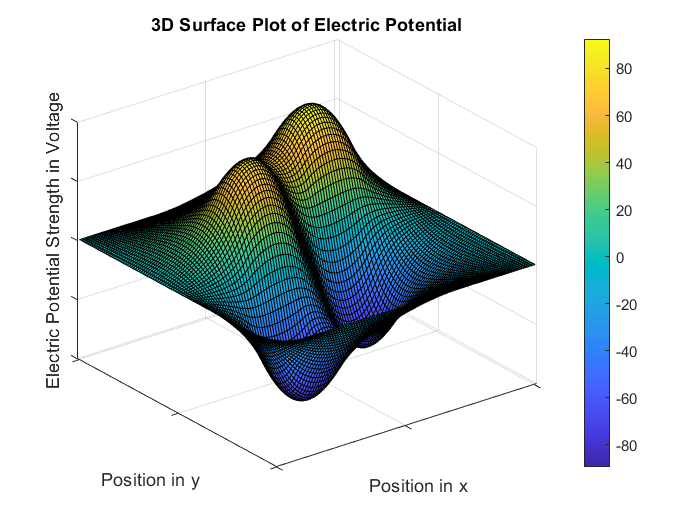

% Plotting the 3D surface plot and contour map
clf; figure(1)
surf(phi(:,:,2))
xlabel('Position in x'), ylabel('Position in y') 
zlabel('Electric Potential Strength in Voltage')
title('3D Surface Plot of Electric Potential')
set(gca,'xticklabel',[],'yticklabel',[],'zticklabel',[])
colorbar

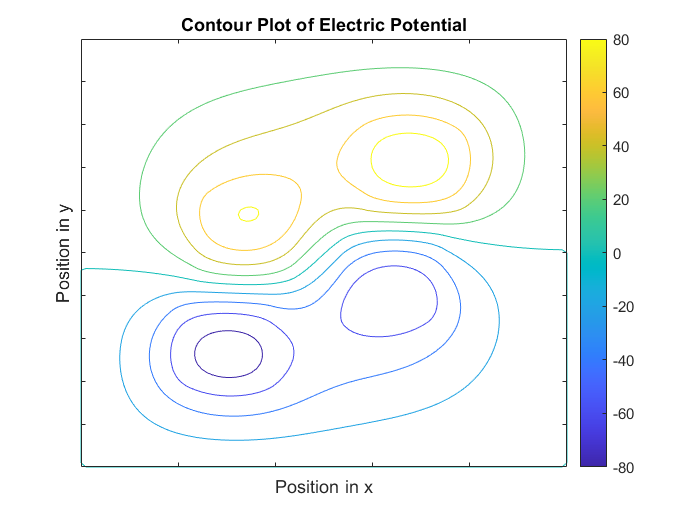

figure(2)
contour(X,Y,phi(:,:,2))
xlabel('Position in x'), ylabel('Position in y')
title('Contour Plot of Electric Potential')
set(gca,'xticklabel',[],'yticklabel',[])
colorbar

#### Gradient and Force Directions

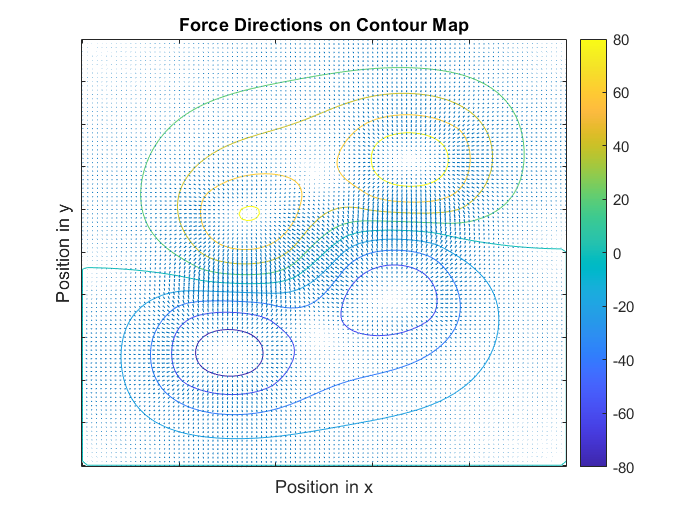

% Plotting the Force Directions on top of the Contour Map
clf; figure()
contour(X,Y,phi(:,:,2))
hold on
[grad_phi_x,grad_phi_y] = gradient(phi(:,:,2));
quiver(X,Y,grad_phi_x,grad_phi_y)
hold off
xlabel('Position in x'), ylabel('Position in y')
title('Force Directions on Contour Map')
set(gca,'xticklabel',[],'yticklabel',[])
colorbar

# Part 3: Animating Eigenmodes of 2D Circular Membrane

### Idea

In this exercise, the idea is to show any eigenmode of 2D circular membrane by animation. The general solution for the modal vibrations of the circular membrane is described by the displacement function:


$$u_{m,n} \left(r,\theta ,t\right)=\left(A\;\cos \;c\lambda_{m,n} t+B\;\sin \;c\lambda_{m,n} t\right)\left(C\;\cos \;m\theta +D\;\sin \;m\theta \right)J_m \left(\lambda_{m,n} r\right)$$


where $c=\textrm{speed}\;\textrm{of}\;\textrm{propagation}$, $\lambda_{m,n} =\alpha_{m,n} /R$, $\alpha_{m,n} =\textrm{Roots}\;\textrm{of}\;\textrm{Bessel}\;\textrm{function}$, $R=\textrm{radius}\;\textrm{of}\;\textrm{the}\;\textrm{membrane}$, and $J_m \left(\lambda_{m,n} r\right)=\textrm{Bessel}\;\textrm{function}$. When $m=0$, the vibration is asymmetric, which means it does not depend on the angle.

To animate this, we will solve $u\left(r,t\right)$within $r\in \left\lbrack 0,R\right)$ for many different $t$ values and set MATLAB to plot $u\left(r,t\right)$with a changing $t$ values.

### Setting Up

We can set our $t$ values such that $u\left(r,t_0 \right)=u\left(r,t_{\textrm{end}} \right)$. This way, we can loop the animation for $t\in \left\lbrack t_0 ,t_{\textrm{end}} \right)$. We can choose our initial time to be $t_0 =0$, and our final time to be $t=\frac{2\pi }{c\lambda_{0,n} }$.

% Clearing the memory
clear; clc; clf;

% Alpha values (Asmar, 2005):
p.alpha = [2.40483,5.52008,8.65373;...
    3.83171,7.01559,10.1735;...
    5.13562,8.41724,11.6198];
p.m = 1;            % Setting the m value within [0,2]
p.n = 1;            % Setting the n value within [1,3]

% Setting up the parameter
p.R = 10;           % Radius
p.A = 1;            % A coefficient
p.B = 1;            % B coefficient
p.C = 1;            % C coefficient
p.D = 1;            % D coefficient
p.lambda = p.alpha(p.m+1,p.n)/p.R;    % Lambda element
p.c = 1;            % Speed of propagation
p.fps = 60;         % Determine the number of frames played in a second
p.t = linspace(0,2*pi/(p.c*p.lambda),p.fps+1);
p.r = linspace(0,p.R,101);
p.theta = linspace(0,2*pi,101);

### Solving the Displacement Function

% Solving the displacement function
u = zeros(length(p.r),length(p.theta),p.fps);
for t = 1:p.fps
    for r = 1:length(p.r) - 1
        for theta = 1:length(p.theta)
            u(r,theta,t) = (p.A*cos(p.c*p.lambda*p.t(t)) + ...
                p.B*sin(p.c*p.lambda*p.t(t))) * ...
                (p.C*cos(p.m*p.theta(theta)) + ...
                p.D*sin(p.m*p.theta(theta))) * ...
                besselj(p.m,p.lambda*p.r(r));
        end
    end
end

### Pre Animation Plotting

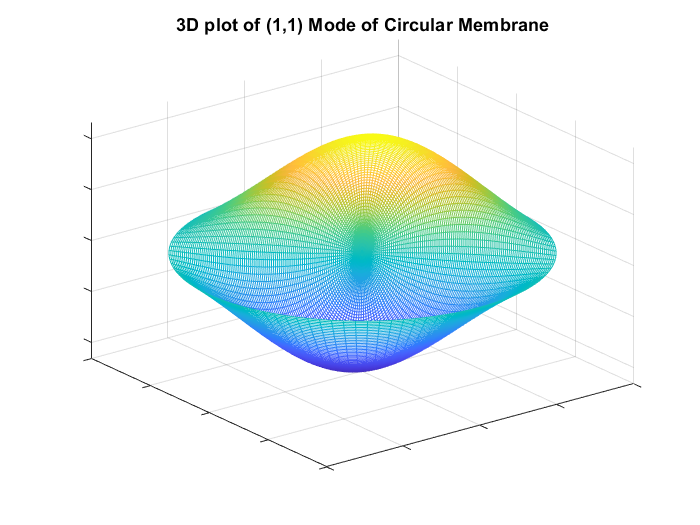

% Switching coordinates
for j = 1:length(p.r)
    for k = 1:length(p.theta)
        x(j,k) = p.r(j)*cos(p.theta(k));
        y(j,k) = p.r(j)*sin(p.theta(k));
    end
end
% Plotting at t = 0, to see if it works so far
clf; figure()
mesh(x,y,u(:,:,1))
title(['3D plot of (',num2str(p.m),',',num2str(p.n), ...
    ') Mode of Circular Membrane'])
set(gca,'xticklabel',[],'yticklabel',[],'zticklabel',[])
axis([-p.R p.R -p.R p.R min(min(min(u))) max(max(max(u)))])

### Animating (m,n) Mode

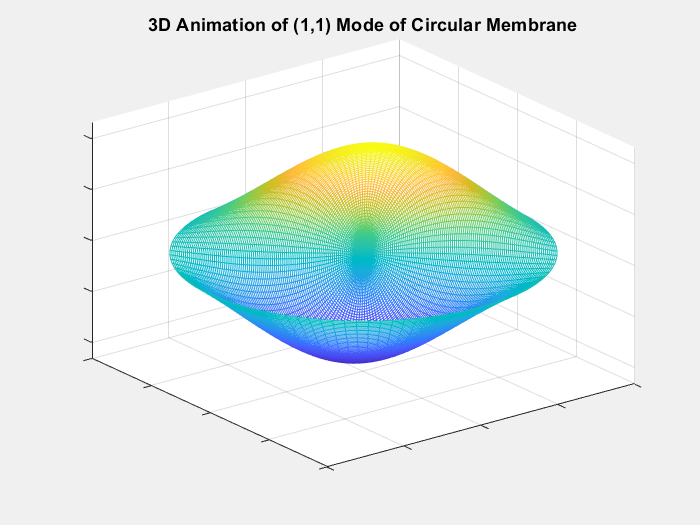

% For all time t
clf; figure() 
f = figure;
f.Visible = 'off';
gif_file = 'Part_3_Animation.gif';
for t = 1:p.fps
    mesh(x,y,u(:,:,t));
    title(['3D Animation of (',num2str(p.m),',',num2str(p.n),...
        ') Mode of Circular Membrane'])
    set(gca,'xticklabel',[],'yticklabel',[],'zticklabel',[])
    axis([-p.R p.R -p.R p.R min(min(min(u))) max(max(max(u)))])
    M(t) = getframe;
    
    % Author: Christopher Bergevin from here
    im = frame2im(M(t));
    [imind,cm] = rgb2ind(im,128);
    if t == 1
        imwrite(imind,cm,gif_file,'gif','Loopcount',inf);
    else
        imwrite(imind,cm,gif_file,'gif','WriteMode','append');
    end
    % to here. Thank You
    
end
f.Visible = 'on';
movie(M,4,p.fps)

# Part 4: Spectrogram of Speech Signal

### Idea

In this exercise, the idea is to make a spectrogram for any speech signal. For any pre-recorded voice signal, a spectrogram is produced using the short time Fourier transform (STFT) process. MATLAB has a built in function "spectrogram" that takes our audio sample and plot its spectrogram.

### Setting Up

% Clearing the memory
clear; clc; clf;

% Write the name of the sound file
s.filename = ["Sound_Sample.m4a","Book 7 Study No 1 Second Take.m4a"];
% Setting the parameters and calling in sound file
s.windowsegment = 2000;             % Length of window segment
s.overlap = 0.95;                   % Fractional overlap between windows
s.max_F = 2000;                     % Max frequency for Spectrogram in Hertz

### Plotting

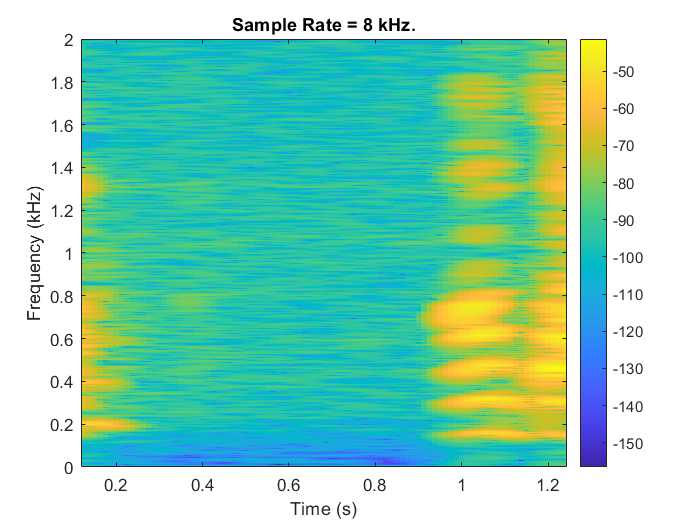

% Plotting the Spectrogram for Sound Sample.m4a, "I'm Johannes"
clf; figure(1)
[s.sounddata,s.samplerate] = audioread([s.filename(1)]);
s.points = round(s.windowsegment*s.overlap);    % Convert overlap to points
spectrogram(s.sounddata,blackman(s.windowsegment),s.points, ...
    s.windowsegment,s.samplerate,'yaxis')
title(['Sample Rate = ',num2str(s.samplerate/1000),' kHz.'])
ax1 = gca; ax1.YLim = [0 s.max_F/1000]; colorbar

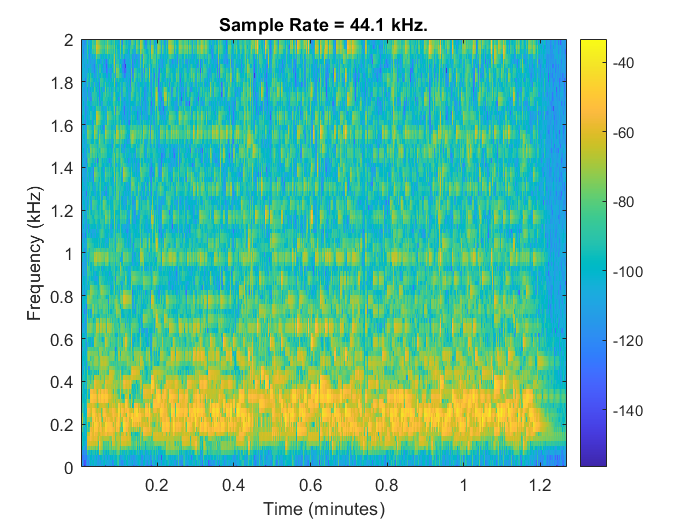

% Plotting the Spectrogram for Book 7 Study No 1 Second Take.m4a
% For fun
figure(2)
[s.sounddata,s.samplerate] = audioread([s.filename(2)]);
s.points = round(s.windowsegment*s.overlap);    % Convert overlap to points
spectrogram(s.sounddata,blackman(s.windowsegment),s.points,...
    s.windowsegment,s.samplerate,'yaxis')
title(['Sample Rate = ',num2str(s.samplerate/1000),' kHz.'])
ax2 = gca; ax2.YLim = [0 s.max_F/1000]; colorbar

# References

- Asmar, Nakhle. *Partial differential equations with Fourier series and boundary value problems, *198*.* Upper Saddle River, N.J.: Pearson Prentice Hall, 2005

- Grewal, B.S.. "Numerical Solution of Partial Differential Equations", in *Numerical Methods in Engineering and Science,* 491-546. Khanna Publishers, 2014

- Newman, Mark. "Partial Differential Equation", in *Computational Physics,* 404-443. University of Michigan, 2012

- Stickler, A. Benjamin and Schachinger, Ewald. "Partial Differential Equation", in *Basic Concepts in Computational Physics, second ed., *157-178. Switzerland: Springer Nature, 2016